# Unsupervised Learning

## Load Data (3-4)

Load and display the processed data stored in ch2_`processedData.mat`.

load ch2_processedData.mat
disp(head(scFeatures))

                            NumberOfElements    MeanAtomicMass    WtdMeanAtomicMass    GmeanAtomicMass    WtdGmeanAtomicMass    EntropyAtomicMass    WtdEntropyAtomicMass    RangeAtomicMass    WtdRangeAtomicMass    StdAtomicMass    WtdStdAtomicMass    MeanFie    WtdMeanFie    GmeanFie    WtdGmeanFie    EntropyFie    WtdEntropyFie    RangeFie    WtdRangeFie    StdFie    WtdStdFie    MeanAtomicRadius    WtdMeanAtomicRadius    GmeanAtomicRadius    WtdGmeanAtomicRadius    EntropyAtomicRadius    WtdEntropyAtomicRadius    RangeAtomicR

Extract the numeric matrix of data from the `superFeatures` table using [`vartype`](matlab: doc vartype)

featureNum = scFeatures(:,vartype("numeric"))

featureNum = 15542×89 table
                                NumberOfElements    MeanAtomicMass    WtdMeanAtomicMass    GmeanAtomicMass    WtdGmeanAtomicMass    EntropyAtomicMass    WtdEntropyAtomicMass    RangeAtomicMass    WtdRangeAtomicMass    StdAtomicMass    WtdStdAtomicMass    MeanFie    WtdMeanFie    GmeanFie    WtdGmeanFie    EntropyFie    WtdEntropyFie    RangeFie    WtdRangeFie    StdFie    WtdStdFie    MeanAtomicRadius    WtdMeanAtomicRadius    GmeanAtomicRadius    WtdGmeanAtomicRadius    EntropyAtomicRadius    WtdEntropyAtomicRadius<

featureData = featureNum.Variables

featureData = 	1.0e+04 *

    0.0002    0.0067    0.0027    0.0054    0.0027    0.0001    0.0000    0.0081    0.0027    0.0040    0.0004    0.0654    0.0578    0.0649    0.0577    0.0001    0.0000    0.0153    0.0575    0.0077    0.0007    0.0141    0.0118    0.0140    0.0118    0.0001    0.0000    0.0047    0.0117    0.0024    0.0002    0.6595    0.2716    0.5322    0.2707    0.0001    0.0000    0.7790    0.2674    0.3895    0.0348    0.0086    0.0044    0.0075    0.0044    0.0001    0.0000    0.0083    0.0044    0.0042
    0.0002    0.0087    0.0066    0.0084    0.0066    0.0001    0.0000    0.0042    0.0065    0.0021    0.0003    0.0818    0.0905    0.0813    0.0905    0.0001    0.0000    0.0175    0.0898    0.0088    0.0012    0.0154    0.0142    0.0153    0.0142    0.0001    0.0000    0.0023    0.0140    0.0011    0.0002    0.8815    0.7157    0.8654    0.7154    0.0001    0.0000    0.3350    0.7052    0.1675    0.0236    0.0064    0.0002    0.0014    0.0002    0.0000    0.0001   

Extract the cleaned matrix of numeric data.

featureDataClean = scFeaturesClean{:, vartype("numeric")};

## Correlation Analysis (3-6)

Calculate the correlation between variables using [`corr`](matlab: doc corr). Remember to use the `"rows", "pairwise"` name value pair to use the maximum number of observations when calculating the correlation.

featureCorr = corr(featureData,"rows","pairwise")

featureCorr =     1.0000   -0.1714   -0.3896   -0.3161   -0.4824    0.9417    0.8812    0.6705   -0.4145    0.4914    0.5324    0.1724    0.5058    0.0255    0.4469    0.9796    0.7087    0.7926    0.2907    0.6881    0.7318   -0.0246   -0.4622   -0.2699   -0.5516    0.9784    0.9036    0.7835   -0.4730    0.6448    0.7089   -0.4585   -0.5401   -0.6542   -0.6717    0.8699    0.7574    0.3753   -0.4325    0.1600    0.3080   -0.1304    0.2044   -0.3646   -0.0499    0.8730    0.6032    0.5116    0.2108    0.3997
   -0.1714    1.0000    0.8044    0.9402    0.7384   -0.1287   -0.1126    0.1138    0.4761    0.1937    0.1174   -0.2833   -0.2247   -0.2328   -0.2165   -0.1979   -0.1803   -0.2778   -0.0768   -0.2969   -0.2487    0.4873    0.3605    0.5553    0.3528   -0.1707   -0.1652   -0.2960    0.1498   -0.3499   -0.3078    0.7496    0.6021    0.6033    0.5302   -0.0522    0.0184    0.1880    0.3724    0.2423    0.1687    0.0882    0.0524    0.2013    0.1413   -0.1207   -0.1279   -0.2079    0

Visualize the correlation matrix with a [`heatmap`](matlab: doc heatmap)`.`

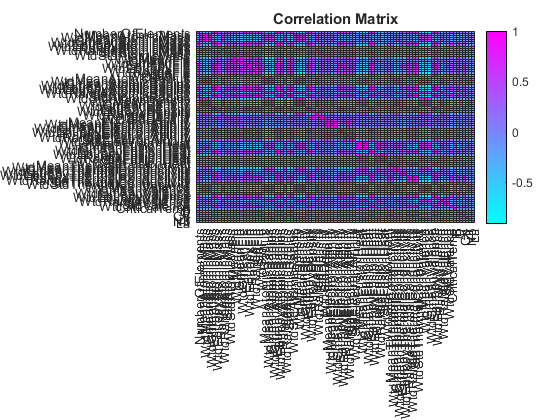

featureNames = string(featureNum.Properties.VariableNames);
heatmap(featureNames, featureNames, featureCorr, "Colormap", cool)
title("Correlation Matrix")

Tabulate the pairs of variables with an absolute correlation greater than 0.95. 

highCorrPairs = triu(abs(featureCorr) > 0.95, 1);
[rIdx, cIdx] = find(highCorrPairs);

highCorrTbl = table(featureNames(rIdx)', featureNames(cIdx)', featureCorr(highCorrPairs), ...
    'VariableNames', ["Variable1", "Variable2", "Correlation"]);
highCorrTbl = sortrows(highCorrTbl, "Correlation", "descend");
disp(highCorrTbl)

            Variable1                      Variable2             Correlation
    __________________________    ___________________________    ___________

    "EntropyFie"                  "EntropyAtomicRadius"            0.99763  
    "WtdMeanValence"              "WtdGmeanValence"                0.99509  
    "WtdMeanFie"                  "WtdGmeanFie"                    0.99273  
    "EntropyFie"                  "EntropyValence"                 0.99251  
    "MeanValence"                 "GmeanValence"                   0.99008  
    "EntropyAtomicRadius"         "EntropyValence"                  0.9896  
    "RangeThermalConductivity"    "StdThermalConductivity"         0.98746  
    "RangeFusionHeat"             "StdFusionHeat"                  0.98452  
    "RangeFie"                    "StdFie"                         0.98203  
    "WtdMeanAtomicRadius"         "WtdGmeanAtomicR

We can see there is signifcant correlations in the data and perhaps not all 85 features are equally informative.  We may be able to eliminate some unecessary information if we can uncover the structure in the data.  To this end we look at PCA which rotates our data in such a way that the directions with the most variation come first.

## Principal Component Analysis (PCA) (3-7)

### Normalizing Data

Create a box plot for each variable.

boxchart(featureDataClean, "MarkerStyle", ".")
xticklabels(featureNames)
grid on
title("Unscaled box plots")

Note that some variables are on a different scale. This will bias any results from PCA.

Use [`normalize`](matlab: doc normalize) to rescale the variables, and visualize the box plots.

%featureNorm = 

boxchart(featureNorm, "MarkerStyle", ".")
xticklabels(featureNames)
grid on
title("Rescaled box plots")

### Coefficients

Perform [`pca`](matlab: doc pca) on the normalized features. Take five outputs.

%[C, S, e, t2, explained] = 

The first output is the coefficient matrix. Visualize the first five columns with a heatmap.

compNames = "PC" + (1:width(C));
heatmap(compNames(1:5), featureNames, abs(C(:, 1:5)), ...
    "Colormap", bone)
title("Coefficient Matrix")

### Scores

The second output are the scores. Visualize the first three components using a [`gplotmatrix`](matlab: doc gplotmatrix)`.`

gplotmatrix(S(:, 1:3), [], scFeaturesClean.TcClass, ...
    [], [], [], [], "grpbars", compNames(1:3))
title("PCA Scores")

## Dimensionality Reduction (3-8)

Dimensionality reduction can help remove redundent information from our dataset, and identify key features. This can help reduce complexity when creating predictive models.

### Selecting Components

Create a [`pareto`](matlab: doc pareto) plot of the variance of the principal components using the third output from `pca`.

ylabel("Variance / Information")
xlabel("Principal Component")
title("Pareto plot")

Calculate the number of components that make up 95% on the variance/information in the data.

varThresh = 95;
numComponents = find(cumsum(explained) > varThresh, 1)

### Selecting Features

Use [`rotatefactors`](matlab: doc rotatefactors) on the coefficient matrix to align the features with a component, and visualize the resulting matrix.

A = rotatefactors(C);
heatmap(compNames, featureNames, abs(A))
title("Aligned Feature Matrix")

Find the features that correspond to the components that make up 95% of information in the data.

[~, impIdx] = max(abs(A));
importantFeatures = featureNames(impIdx(1:numComponents))'

## t-Distributed Stochastic Neighborhood Embedding (tSNE) (3-9)

Sample 3000 observations from the normalized features using [`datasample`](matlab: doc datasample)`.`

[featureSample, sampleIdx] = datasample(featureNorm, 3000);

Use [`tnse`](matlab: doc tsne) on the data sample, and visualize the output grouped by critical temperature.

%Z = 

gscatter(Z(:, 1), Z(:, 2), scFeaturesClean.TcClass(sampleIdx))
grid on
title("Data visualized in tSNE coordinates")
xlabel("tSNE-x")
ylabel("tSNE-y")

## k-Means Clustering (3-11)

Create a `Cluster Data` live task to cluster the normalized features using the [`kmeans`](matlab: doc kmeans) algorithm. 

% Perform k-means clustering using specified number of clusters (K value)
%K = 
%[kmeansIdx,kmeansCentroids] = 
clear K

% Display results

% Display 2D scatter plot (PCA)
figure
[~,score] = pca(featureNorm);
clusterMeans = grpstats(score,kmeansIdx,"mean");
h = gscatter(score(:,1),score(:,2),kmeansIdx,colormap("lines"));
for i = 1:numel(h)
    h(i).DisplayName = strcat("Cluster",h(i).DisplayName);
end
clear h i score
hold on
h = scatter(clusterMeans(:,1),clusterMeans(:,2),50,"kx","LineWidth",2);
hold off
h.DisplayName = "ClusterMeans";
clear h clusterMeans
legend;
title("First 2 PCA Components of Clustered Data");
xlabel("First principal component");
ylabel("Second principal component");

## Interpreting Clusters (3-12)

Create a [`parallelcoords`](matlab: doc parallelcoords) (parallel plot) of the normalized features using the $k$-means clustering results.

parallelcoords(featureNorm, ...
    "Group", kmeansIdx, ...
    "Quantile", 0.25, ...
    "Labels", featureNames)
title("Parallel Plot of kmeans clusters")
grid on

Recreate the [parallel plot](#M_6DD2AC0B) by reordering the features using the centroid difference.

reorderedParallelCoords(featureNorm, kmeansIdx, kmeansCentroids, featureNames);

Using [crosstab](matlab: doc crosstab), visualize the counts of high and low temperature superconductors in each cluster.

kmeansCt = crosstab(scFeaturesClean.TcClass, kmeansIdx);

bar3(kmeansCt)
yticklabels(categories(scFeaturesClean.TcClass))
zlabel("Count")
title("Superconductor type in cluster")

## Gaussian Mixture Models (GMM) (3-13)

Fit a guassian mixture model on the superconductor data using [fitgmdist](matlab: doc fitgmdist).

rng default

gmMdl = fitgmdist(S(:, 1:numComponents), 2, "Replicates", 10)

Find the centroid locations.

gmCentroids = gmMdl.mu;

[cluster](matlab: web(fullfile(docroot, 'stats/gmdistribution.cluster.html'))) the data to return the group index for each observation.

[gmIdx, ~, probScore] = cluster(gmMdl, S(:, 1:numComponents));

Visualize the results.

gscatter(S(:, 1), S(:, 2), gmIdx)
grid on
title("GMM Clustering results")
xlabel(compNames(1))
ylabel(compNames(2))
hold on
scatter(gmCentroids(:, 1), gmCentroids(:, 2), 100, "k*", ...
    "DisplayName", "Centroids")

Use the third output from `cluster` to visualize and tabulate materials that have low probability of belonging to any cluster. 

uncertainIdx = all(probScore < 0.75, 2);
scatter(S(uncertainIdx, 1), S(uncertainIdx, 2), "filled", ...
    "DisplayName", "Uncertain Points")
hold off
disp(scFeaturesClean(uncertainIdx, :))

### Interpretation

Visualize the [bivariate histogram](#M_6DD2AC0B) for each cluster.

ghistogram2(S, gmIdx, 100);

Calculate the centroid locations in feature space. 

gmmCentroidsFeatures = gmCentroids * C(:, 1:numComponents)';

Visualize the reordered parallel plot.

reorderedParallelCoords(featureNorm, gmIdx, gmmCentroidsFeatures, featureNames)

Visualize the counts of high and low temperature superconductors in each cluster.

gmmCt = crosstab(scFeaturesClean.TcClass, gmIdx);
bar3(gmmCt)
yticklabels(categories(scFeaturesClean.TcClass))
zlabel("Count")
title("Count of superconductor in GMM Cluster")

## Evaluating the clustering results (3-14)

Run [evalclusters](matlab: doc evalclusters) to determine the optimal number of clusters for each clustering method.

kList = 2:8;
%ev = 

plot(ev.InspectedK, ev.CriterionValues, "o-", "LineWidth", 2)
grid on
xlabel("Number of clusters (k)")
ylabel("Criterion Metric")
title("Cluster Evaluation Results")
optimalIdx = ev.InspectedK == ev.OptimalK;
hold on
scatter(ev.InspectedK(optimalIdx), ev.CriterionValues(optimalIdx), "filled", "ro")
hold off
legend("Metric", "Optimal K", "Location", "best")

## Hierarchical Clustering (3-15)

Calculate the pairwise distance between features using [pdist](matlab: doc pdist).

featureDist = pdist(featureNorm');

Create a hierarchical clustering of features using a [linkage](matlab: doc linkage) of pairwise distances.

%featureLinkage = 

Visualize a [dendrogram](matlab: doc dendrogram) of the hierarchical clustering results.

colorThresh = 800;
[~, ~, leafOrder] = dendrogram(featureLinkage, length(featureNames), ...
    "Labels", featureNames, ...
    "Orientation", "right", ...
    "ColorThreshold", colorThresh);
xline(colorThresh, "--")
title("Dendrogram of hierarchical clustering")

## Save results

save clusteredData importantFeatures gmIdx scFeaturesClean t2OutlierIdx

## Local Functions

function ghistogram2(S, gIdx, nBins)
labels = unique(gIdx);
pc1Edges = linspace(min(S(:,1)), max(S(:,1)), nBins);
pc2Edges = linspace(min(S(:,2)), max(S(:,2)), nBins);
figure
for k = labels'
    histogram2(S(gIdx == k, 1), S(gIdx == k, 2), ...
        pc1Edges, pc2Edges, "Normalization", "pdf")
    hold on
end
xlabel("PC1")
ylabel("PC2")
legend("Cluster " + labels, "Location", "best")
title("GMM Clustering results as a bivariate histogram")
end

function reorderedParallelCoords(features, gIdx, centroids, featureNames)
centroidDiff = diff(centroids);
[~, sortIdx] = sort(centroidDiff);
figure
parallelcoords(features(:, sortIdx), ...
    "Group", gIdx, ...
    "Quantile", 0.25, ...
    "Labels", featureNames(sortIdx))
title("Reordered parallel plot")
grid on
end